clear
l = [0, 10.6, 10.6, 7.6];
qini = [0,0,0,0];
offset = [0, pi/2, 0, 0];
% Orden parametros funcion link [THETA D A ALPHA SIGMA(0R,1P) OFFSET]
DHparameters = [qini(1) 4.8 l(1) pi/2 0 offset(1);
                qini(2) 0   l(2) 0    0 offset(2);
                qini(3) 0   l(3) 0    0 offset(3);
                qini(4) 0   l(4) pi/2    0 offset(4)];
L(1) = Link(DHparameters(1,:));
L(2) = Link(DHparameters(2,:));
L(3) = Link(DHparameters(3,:));
L(4) = Link(DHparameters(4,:));
Robot_pincher = SerialLink(L,'name','Pincher');
ws = [-30 30 -30 30 -10 50];
%Robot_pincher.plot(qini,'workspace',ws);

y=0.01

y = 0.0100

x=30

x = 30

z=7.7

z = 7.7000

q=double(round(ikine(x,y,z),3))

q =          0   -0.0530   -0.5180    0.5720


qfin=[q(1), pi/2-q(2),-q(3),-q(4)]

qfin =          0    1.6238    0.5180   -0.5720


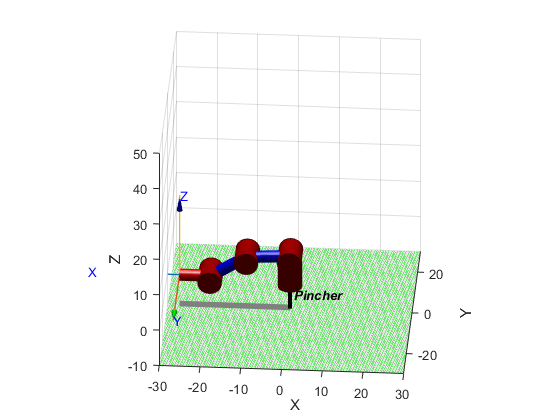

view([4 30]);
Robot_pincher.plot(qfin,'workspace',ws);

function q = ikine(x,y,z)
syms theta2 theta3;
l1=9.2;
l2=4.8; 
l3=10.6;
l4=10.6; 
l5=10.5;
theta1=double(vpa(atan(y/x)));
eqn1 = z == l1+l2+sin(theta2)*l3+sin(theta2+theta3)*l4;
eqn3 = y == sin(theta1)*(cos(theta2)*l3+cos(theta2+theta3)*l4+l5);
S = solve([eqn1 eqn3],[theta2 theta3],'Real',true);
theta4=-(vpa(S.theta2(1))+vpa(S.theta3(1)));
q=[theta1 vpa(S.theta2(1)) vpa(S.theta3(1)) theta4];
end